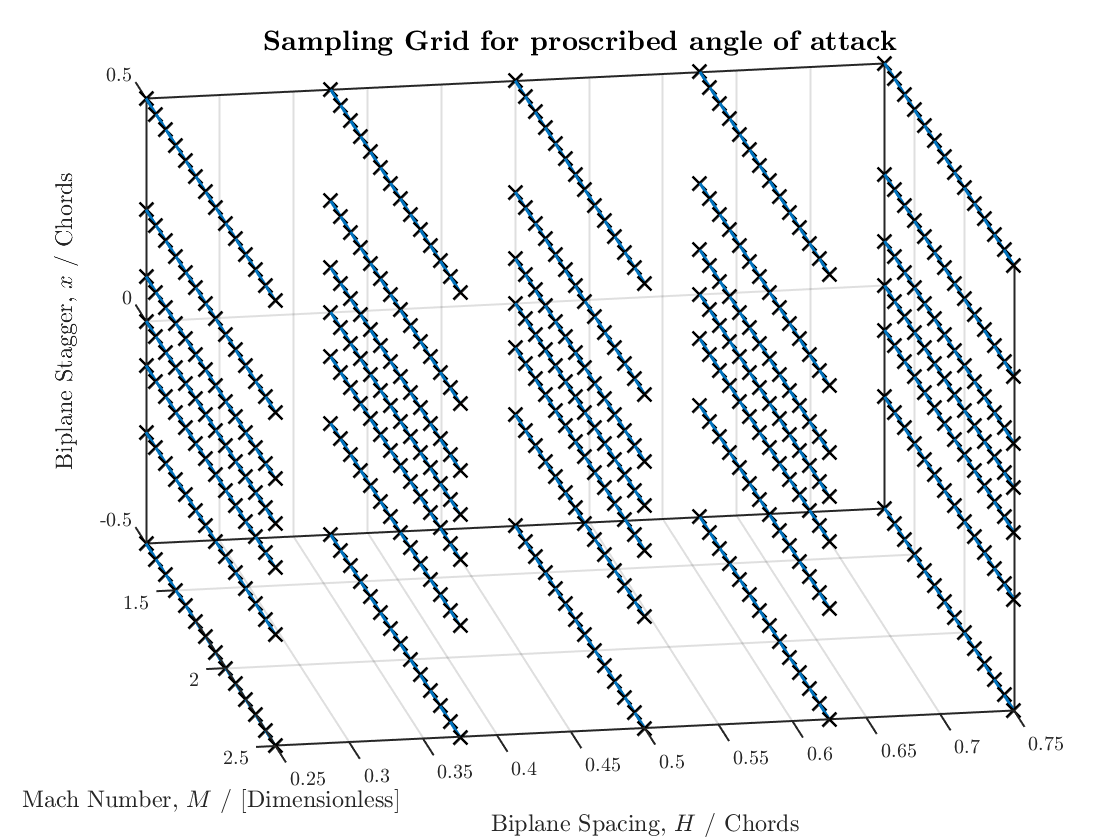

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880];
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Summary

% Inputs
%     vector of Mach Numbers / Dimensionless = Machs
%     vector of Spacings / Chords            = Spacings
%     vector of Staggers / Chords            = Staggers
%     vector of AoA / Chords (Angles) - set as a 1 off for now)%
% Output
%     Array (3D) of Cdwave.Ma^2 coefficients = DragsMaSqr
%     Array (3D) of Cl.Ma^2 coefficients     = LiftMaSqr

% Each Sim runs a Spacing and Stagger Combination through a range of Mach Numbers
% Establish these vectors

% In a loop generate these Case commands

% Set off all sims as a bash Script cd- <CASE> "Commands inc. MeshGen and rhoCentralFoam" & ... & ... and run for completion
% All the results are sent to these <CASE>'s "/postProcessing/forceCoeffs1/0.frceCoeffs.dat" file

% Collect the results "<CASE>/postProcessing/forceCoeffs1/0.frceCoeffs.dat" in pre-allocated
% arrays: DragsMaSqr, LiftMaSqr
% (obtain coeff by dividing each entity by Ma.^2)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

t_ramp = 10; t_hold = 25;
Machs_mod = [1.2,1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
%Machs_mod = flip(Machs_mod); % for a deceleration case
Spacings_mod = [0.25,0.375,0.5,0.625,0.75];
Staggers_mod = [-0.5,-0.25,-0.1,0,0.1,0.25,0.5];
Angles_mod = [0,1,3]; 

%%
%%
alfa=Angles_mod(1);
%alfa=Angles_mod(2)
%alfa=Angles_mod(3)
%%
%%

[X,Y,Z]=meshgrid(Machs_mod,Spacings_mod,Staggers_mod);
point.Mach=X ; point.Spacing=Y ; point.Stagger=Z;
point.Angle = alfa*ones(size(point.Mach));

for i =1:length(Staggers_mod)
    for j =1:length(Spacings_mod)
    plot3(point.Mach(j,:,i),point.Spacing(j,:,i),point.Stagger(j,:,i),'x-','LineWidth',width,'MarkerSize',msize,'color',blue,'MarkerEdgeColor',black)    % draw the scatter plot
    hold on
    end
end
grid on; box on; hold on
title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view([80.057 24.787])
xlim([1.2 2.5])
%InSet = get(gca, 'TightInset'); set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off
H=gca; H.LineWidth=1;

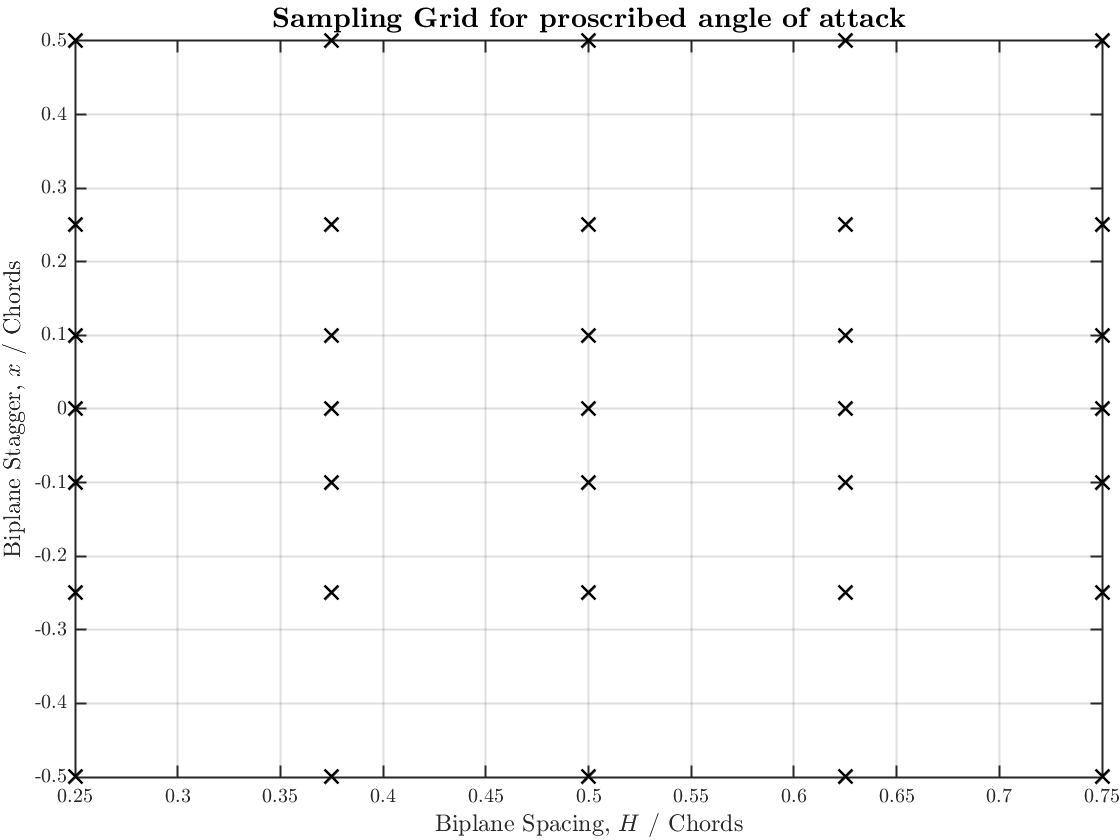


[X,Y,Z]=meshgrid(Machs_mod,Spacings_mod,Staggers_mod);
point.Mach=X ; point.Spacing=Y ; point.Stagger=Z;
point.Angle = alfa*ones(size(point.Mach));

for i =1:length(Staggers_mod)
    plot3(point.Mach(:,:,i),point.Spacing(:,:,i),point.Stagger(:,:,i),'kx','LineWidth',width,'MarkerSize',msize)    % draw the scatter plot
    hold on
end
grid on; box on; hold on
title("\textbf{Sampling Grid for proscribed angle of attack}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Biplane Spacing, $H$ / Chords",'FontSize',lsize)
zlabel("Biplane Stagger, $x$ / Chords",'FontSize',lsize)
view([90 0])
%InSet = get(gca, 'TightInset'); set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% TIME THINGS
t_single_real = 4500*(t_hold/25); %seconds for a 25 second sim
lowest_speed = 1.2; %Mach AND m/s
domain_rad = 6;
t_cross_real = domain_rad/lowest_speed; %call it 10sec to be safe

t_inbetween_real = 4500*t_ramp/25;
t_onespeed = t_ramp+t_hold;
t_onespeed_real = t_single_real+t_cross_real;
t_run_real = length(Machs_mod)*t_onespeed_real;
hrs_runs = t_run_real/3600

hrs_runs = 17.5194


Machs_all = reshape( cat( 1, [Machs_mod], [Machs_mod] ), 1, [] );

t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs_mod)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end
t_all %A vector of all the time instances where a speed stops, starts or changes

t_all =      0    25    35    60    70    95   105   130   140   165   175   200   210   235   245   270   280   305   315   340   350   375   385   410   420   445   455   480


endtime = t_all(end)

endtime = 480

Umag1 = Machs_all(1)

Umag1 = 1.2000


% This function makes the text file, in a function at codes base
Velprofile=speeds(Machs_all,t_all,alfa)

Velprofile = 28×16 char array
    '→(  0 (1.2 0 0))'
    '→( 25 (1.2 0 0))'
    '→( 35 (1.3 0 0))'
    '→( 60 (1.3 0 0))'
    '→( 70 (1.4 0 0))'
    '→( 95 (1.4 0 0))'
    '→(105 (1.5 0 0))'
    '→(130 (1.5 0 0))'
    '→(140 (1.6 0 0))'
    '→(165 (1.6 0 0))'
    '→(175 (1.7 0 0))'
    '→(200 (1.7 0 0))'
    '→(210 (1.8 0 0))'
    '→(235 (1.8 0 0))'
    '→(245 (1.9 0 0))'
    '→(270 (1.9 0 0))'
    '→(280 (  2 0 0))'
    '→(305 (  2 0 0))'
    '→(315 (2.1 0 0))'
    '→(340 (2.1 0 0))'
    '→(350 (2.2 0 0))'
    '→(375 (2.2 0 0))'
    '→(385 (2.3 0 0))'
    '→(410 (2.3 0 0))'
    '→(420 (2.4 0 0))'
    '→(445 (2.4 0 0))'
    '→(455 (2.5 0 0))'
    '→(480 (2.5 0 0))'


% This optionally writes to a text file called 'test.txt' in a pastable
% format
dlmwrite('velocities.txt',Velprofile,'delimiter','');
%edit test.txt

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %% SAMPLING %%
t_sampling=t_all(2:2:end)

t_sampling =     25    60    95   130   165   200   235   270   305   340   375   410   445   480


% these are the columns in the file
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
% these are the line locations to sample on
t_lines_access = (t_sampling)%+9

t_lines_access =     25    60    95   130   165   200   235   270   305   340   375   410   445   480


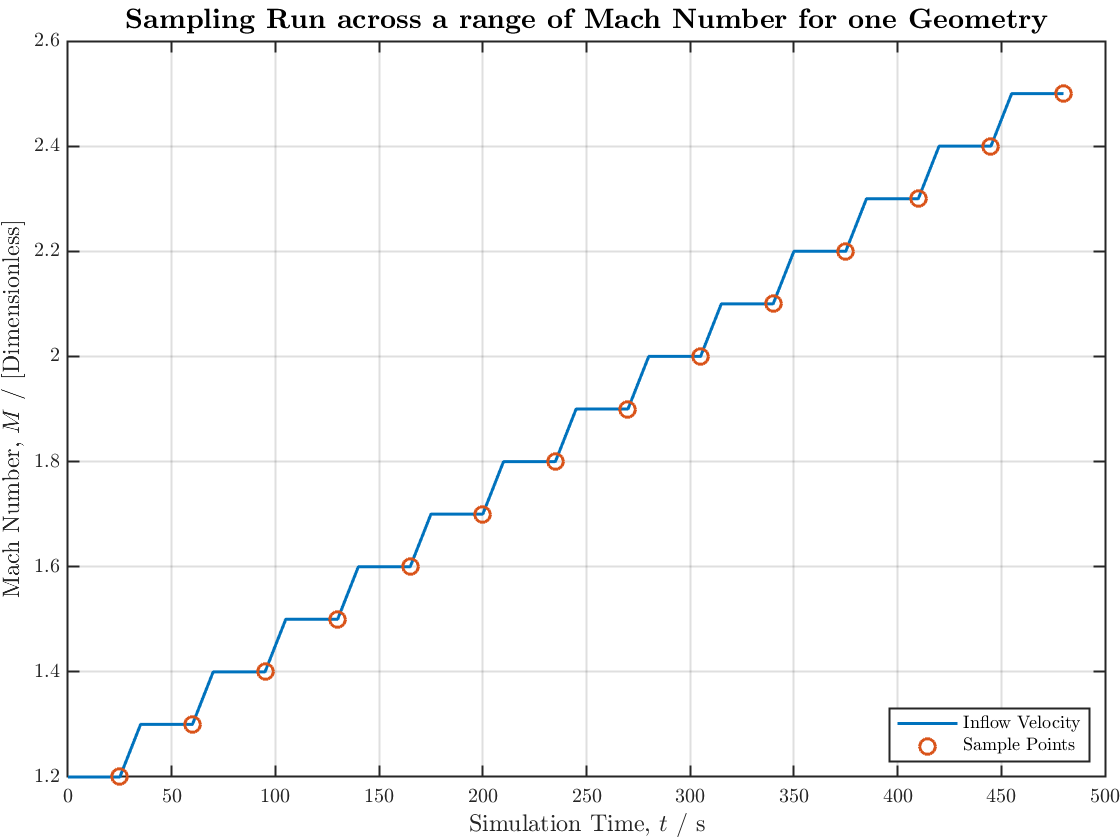


figure
plot(t_all,Machs_all,'-','LineWidth',width,'MarkerSize',msize)
hold on
plot(t_sampling,Machs_mod,'o','LineWidth',width,'MarkerSize',msize)
grid on; box on; hold on
title("\textbf{Sampling Run across a range of Mach Number for one Geometry}",'FontSize',tsize)
ylabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
xlabel("Simulation Time, $t$ / s",'FontSize',lsize)
legend('Inflow Velocity', 'Sample Points','Location',"southeast")
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;

function Velprofile = speeds(Machs_all,t_all,alfa)
% this function reterns the pullTable values for the OpenFOAM in:
% <CASE>/0/include/initialConditions in the form
%(0 (1.3 0 0))
%(25 (1.3 0 0))
%(35 (1.4 0 0))
%(25 (1.5 0 0))

t_entry = num2str(transpose(t_all));
Ux = num2str(cosd(alfa).*transpose(Machs_all));
Uy = num2str(sind(alfa).*transpose(Machs_all));
Uz = num2str(zeros(length(Machs_all),1));

holder=zeros(length(Machs_all),1); s1=holder;s3=holder;space=holder;tabs=holder;
s11 = '(';s33 = ')'; spacechar = ' '; tab = '	';
for i=1:length(Machs_all)
    s1(i,1)=s11;s3(i,1)=s33; space(i,1)=spacechar; tabs(i,1)=tab;
end
s_speed = strcat(Ux,space,Uy,space,Uz);
Velprofile=strcat(tabs,s1,t_entry,space,s1,s_speed,s3,s3);
end